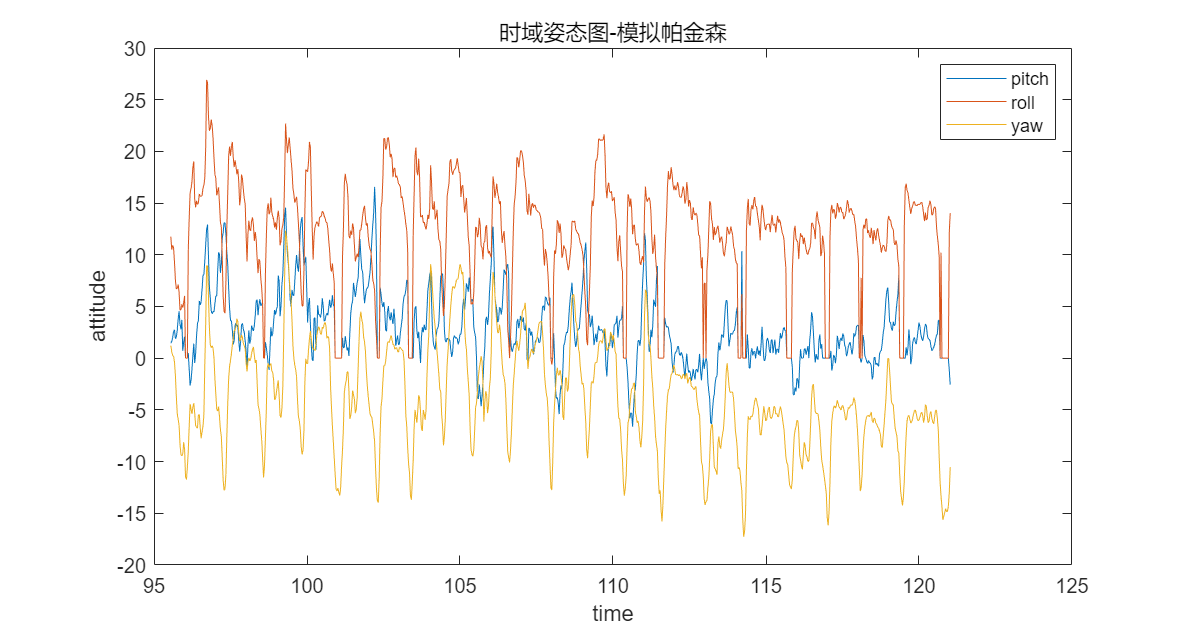

figure('units','normalized','position',[0.1,0.1,0.7,0.6])
%导入模拟帕金森写字的数据
plot(dataset_pd{:, "time"}, dataset_pd{:, "pitch"}, dataset_pd{:, "time"}, dataset_pd{:, "roll"}, dataset_pd{:, "time"}, dataset_pd{:, "yaw"});
xlabel("time")
ylabel("attitude")
title('时域姿态图-模拟帕金森')
legend('pitch', 'roll', 'yaw')

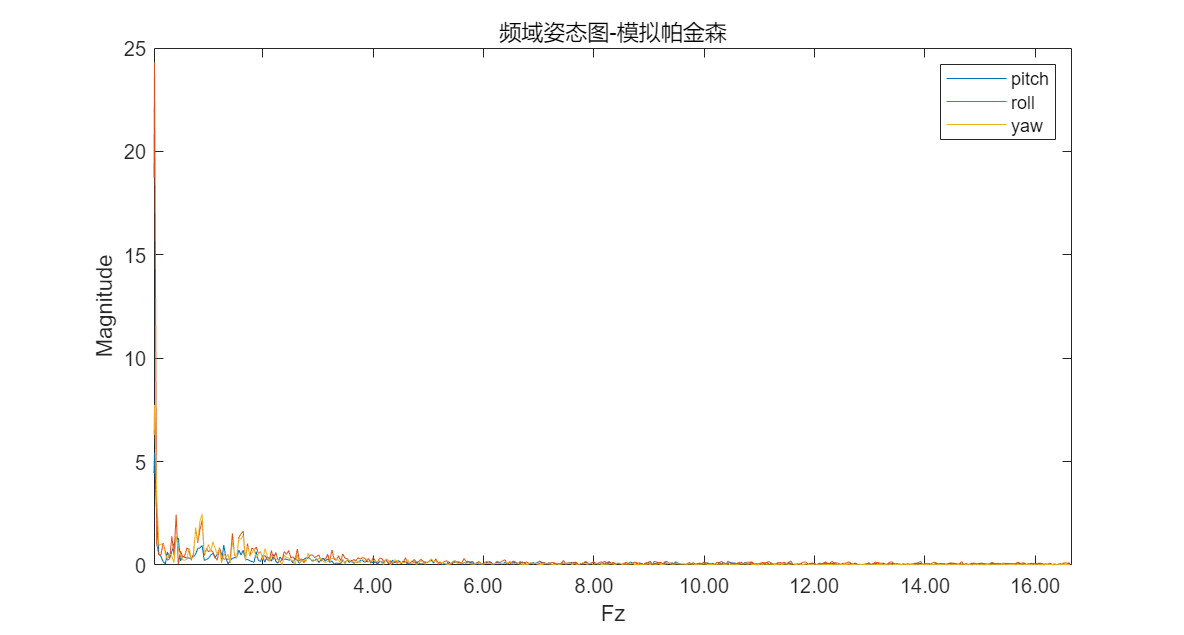

%序列长度
N1 = length(dataset_pd{:, "pitch"});
%采样频率
Fs = 1 / 0.03;
%快速傅里叶变换
dataset_pitch_f = abs(fftshift(fft(dataset_pd{:, "pitch"})));
%仅取0~Fs并进行幅值修正
pitch_fft = 2 * dataset_pitch_f(N1 / 2 : N1 - 1) / N1;%修正交流
pitch_fft(1) = pitch_fft(1) / 2;%修正直流

%快速傅里叶变换
dataset_roll_f = abs(fftshift(fft(dataset_pd{:, "roll"})));
%仅取0~Fs并进行幅值修正
roll_fft = 2 * dataset_roll_f(N1 / 2 : N1 - 1) / N1;%修正交流
roll_fft(1) = roll_fft(1) / 2;%修正直流

%快速傅里叶变换
dataset_yaw_f = abs(fftshift(fft(dataset_pd{:, "yaw"})));
%仅取0~Fs并进行幅值修正
yaw_fft = 2 * dataset_yaw_f(N1 / 2 : N1 - 1) / N1;%修正交流
yaw_fft(1) = yaw_fft(1) / 2;%修正直流

%x轴
f1 = (N1 / 2 : N1 - 1) * Fs / N1 - Fs / 2;

plot(f1, pitch_fft, f1, roll_fft, f1, yaw_fft);
xlabel("Fz");
xlim([1/Fs Fs/2]);
xtickformat('%.2f');
ylabel("Magnitude");
title('频域姿态图-模拟帕金森');
legend('pitch', 'roll', 'yaw');

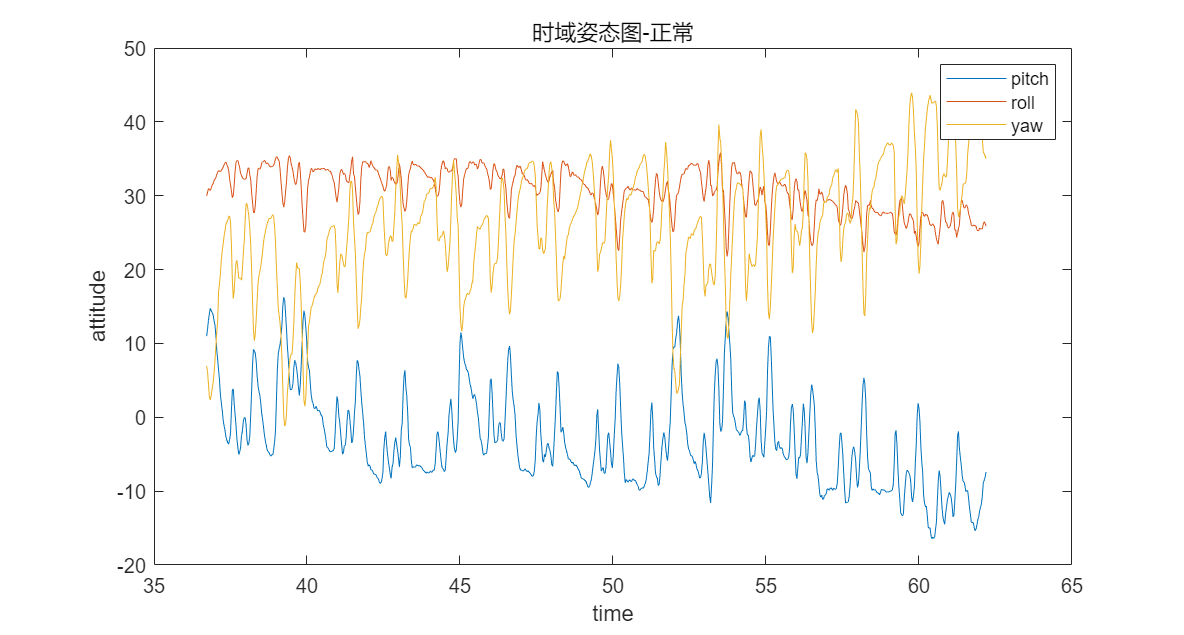

%导入正常写字的数据
plot(dataset_upd{:, "time"}, dataset_upd{:, "pitch"}, dataset_upd{:, "time"}, dataset_upd{:, "roll"}, dataset_upd{:, "time"}, dataset_upd{:, "yaw"});
xlabel("time")
ylabel("attitude")
title('时域姿态图-正常')
legend('pitch', 'roll', 'yaw')

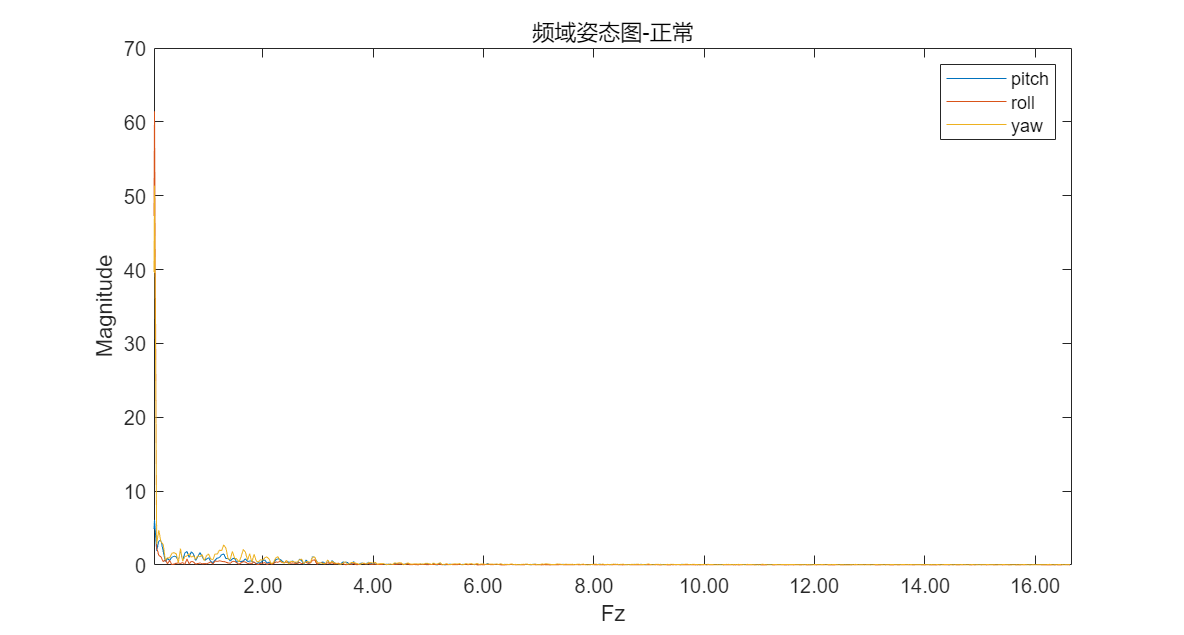

%序列长度
N2 = length(dataset_upd{:, "pitch"});
%快速傅里叶变换
dataset_pitch_uf = abs(fftshift(fft(dataset_upd{:, "pitch"})));
%仅取0~Fs并进行幅值修正
pitch_fft_u = 2 * dataset_pitch_uf(N2 / 2 : N2 - 1) / N2;%修正交流
pitch_fft_u(1) = pitch_fft_u(1) / 2;%修正直流

%快速傅里叶变换
dataset_roll_uf = abs(fftshift(fft(dataset_upd{:, "roll"})));
%仅取0~Fs并进行幅值修正
roll_fft_u = 2 * dataset_roll_uf(N2 / 2 : N2 - 1) / N2;%修正交流
roll_fft_u(1) = roll_fft_u(1) / 2;%修正直流

%快速傅里叶变换
dataset_yaw_uf = abs(fftshift(fft(dataset_upd{:, "yaw"})));
%仅取0~Fs并进行幅值修正
yaw_fft_u = 2 * dataset_yaw_uf(N2 / 2 : N2 - 1) / N2;%修正交流
yaw_fft_u(1) = yaw_fft_u(1) / 2;%修正直流

%x轴
f2 = (N2 / 2 : N2 - 1) * Fs / N2 - Fs / 2;

plot(f2, pitch_fft_u, f2, roll_fft_u, f2, yaw_fft_u);
xlabel("Fz");
xlim([1/Fs Fs/2]);
xtickformat('%.2f');
ylabel("Magnitude");
title('频域姿态图-正常');
legend('pitch', 'roll', 'yaw');

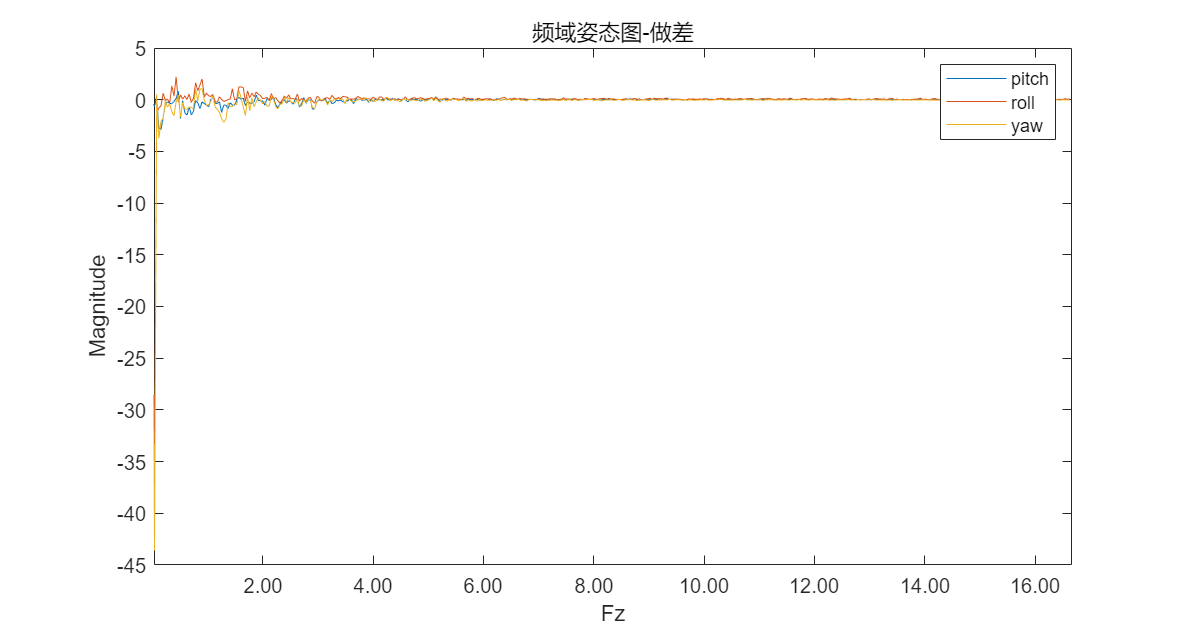

%将模拟帕金森与正常的频域做差
pitch_fft_sub = pitch_fft - pitch_fft_u;
roll_fft_sub = roll_fft - roll_fft_u;
yaw_fft_sub = yaw_fft - yaw_fft_u;

plot(f2, pitch_fft_sub, f2, roll_fft_sub, f2, yaw_fft_sub);
xlabel("Fz");
xlim([1/Fs Fs/2]);
xtickformat('%.2f');
ylabel("Magnitude");
title('频域姿态图-做差');
legend('pitch', 'roll', 'yaw');

%对模拟帕金森信号进行滤波，采用有限脉冲响应滤波器FIR，通过对频域加窗滤除帕金森震颤带来的影响，还原出没有震颤的数据。
%这里假设模拟和正常除了震颤其他因素都一样，即上述做差得到的非零值都是应该滤除的
